# Interpolazione di dati

In questo capitolo saranno presentate tutte le funzionalità del Matalb viste a lezione per quanto riguarda il fitting di dati: in primo luogo si descriverà il tool sviluppato per l'interpolazione di punti inseriti dall'utente, e poi si presenteranno una serie di esempi applicativi delle tecniche di cui sopra. 

## Tool per il confronto di interpolazioni

E' stato realizzato un tool in grado di confrontare alcune delle varie tipologie di interpolazioni realizzabili in Matlab, per poterne apprezzare le caratteristiche. Il tool è eseguibile chiamando la funzione `plot_interpolation.m`.

In particolare, per utilizzare il tool bisogna:

- Cliccare sul tasto `'Seleziona punti'`

- Utilizzare il tasto sinistro del mouse per selezionare i punti con ordine di ascissa crescente

- Utilizzare il tasto destro del mouse per selezionare l'ultimo punto, che ovviamente avrà il più elevato valore di ascissa

- Selezionare il tipo di interpolazione desiderata dal menù a tendina. In particolare, è possibile selezionare l'interpolazione *lineare*, *polinomiale o *tramite *spline naturale *(oppure si possono visualizzare tutte sul grafico)

- Premere il tasto `Close` per uscire dal tool.

Di seguito, a scopo esemplificativo, saranno riportati alcuni esempi, attraverso cui si può facilmente osservare che attraverso l'interpolazione lineare non si ottiene una curva sinuosa, che con la polinomiale all'aumentare del numero di punti si hanno problemi di efficienza e che la spline naturale è il miglior metodo per l'interpolazione di punti.

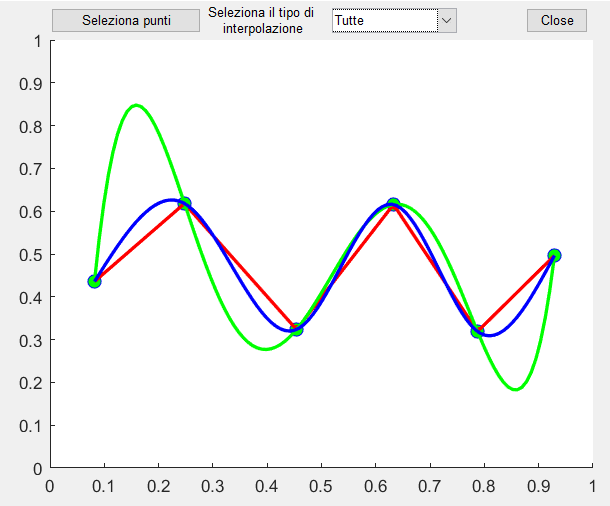

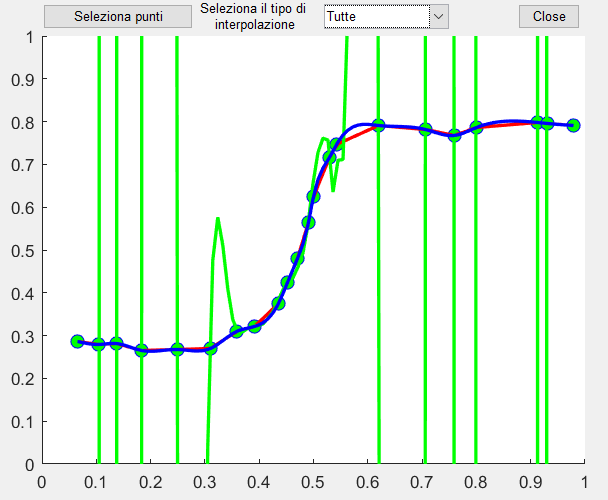

N.B. All'aumentare dei punti, il risultato ottenuto dall'interpolazione polinomiale diventa sempre più oscillante e meno accurato; l'output potrebbe quindi essere poco gradevole.

## Consumo medio di cibo negli Stati Uniti

In questo capitolo saranno applicate le tecniche di interpolazione numerica viste a lezione sul dataset *Data_Consumption,* disponibile all'interno del *Econometrics Toolbox* di Matlab [3]. 

In particolare, il dataset contiene i dati annuali sul prezzo e sul consumo medio del cibo negli Stati Uniti nel periodo 1927-1962, escludendo i dati relativi agli anni della Seconda Guerra Mondiale (1942-1947). Gli obiettivi saranno:

- Recuperare informazioni nel periodo non noto;

- Ricostruire con una risoluzione più precisa l'andamento dei dati.

Innanzitutto si carica il dataset:

load Data_Consumption.mat
% bisogna escludere i valori NaN degli anni della 2° Guerra Mondiale
right_value_index = find(~isnan(Data(:,1))); 
years = dates(right_value_index);
price = Data(right_value_index,1);
income = Data(right_value_index,2);
consumption = Data(right_value_index,3);

Di seguito è mostrato l'andamento dei prezzi:

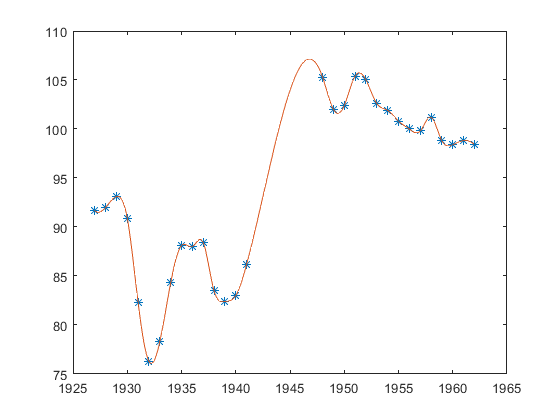

pp = spline(years,price);
t = 1927:0.1:1962;
ys = ppval(pp,t);
plot(years,price,'*',t,ys)

Come ci si aspetta, la funzione interpolante evidenzia che:

- Negli anni della guerra il prezzo del cibo è salito vertiginosamente;

- Le conseguenze della guerra si sono sentite anche negli anni successivi (almeno fino al 1962) in cui il prezzo del cibo, pur abbassandosi, non si è riassestato a quello che c'era prima dell'inizio della guerra.

Facendo lo stesso ragionamento per il fabbisogno di cibo della popolazione (si è scelto di utilizzare la spline cubica naturale per minimizzare le oscillazioni) si osserva ancora che l'aumento più critico si registra nel periodo della Seconda Guerra Mondiale.

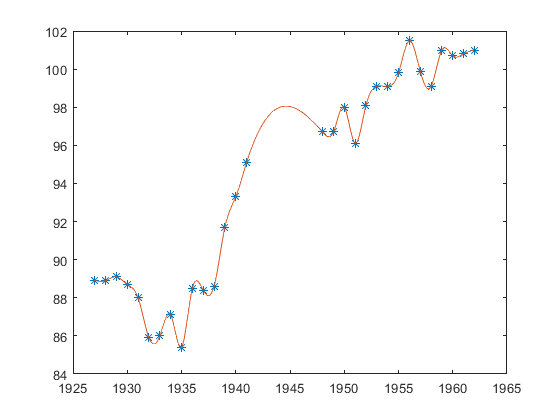

pp = csape(years,consumption,'second');
t = 1927:0.1:1962;
ys = ppval(pp,t);
plot(years,consumption,'*',t,ys) 

Si osserva come la grande quantità di punti renda impossibile utilizzare la tecnica del polinomio interpolante: la funzione `polyfit,` infatti, evidenzia un warning di polinomio malcondizionato e il grafico risultante non rispecchia in alcun modo il fenomeno che si vuole osservare.

p = polyfit(years,price,length(price)-1);

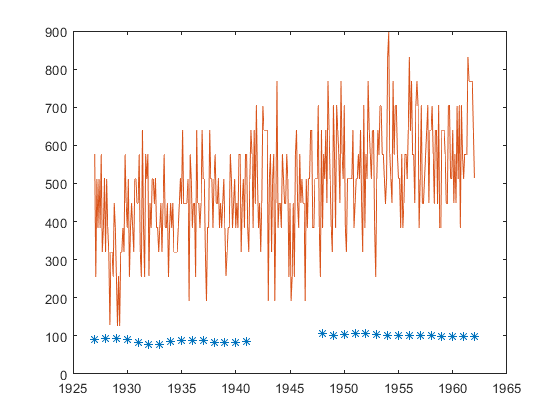

f = polyval(p,t);
plot(years,price,'*',t,f)

## Estrapolazione e previsione

Di seguito è mostrato un esempio in cui l'utilizzo della funzione `fnxtr` permette di prevedere il comportamento della funzione `atan` (funzione arcotangente) del Matlab: da un lato si osserva che il comportamento stimato è molto simile a quello reale, infatti le curve si sovrappongono e "a regime" la spline, pur superando la funzione, rispetta la condizione sull'asintoto orizzontale dell'arcotangente; dall'altro lato è evidente come questa funzionalità non sia riproducibile con un semplice polinomio interpolante che assume nulla la funzione nei valori esterni all'intervallo in cui l'abbiamo considerata.

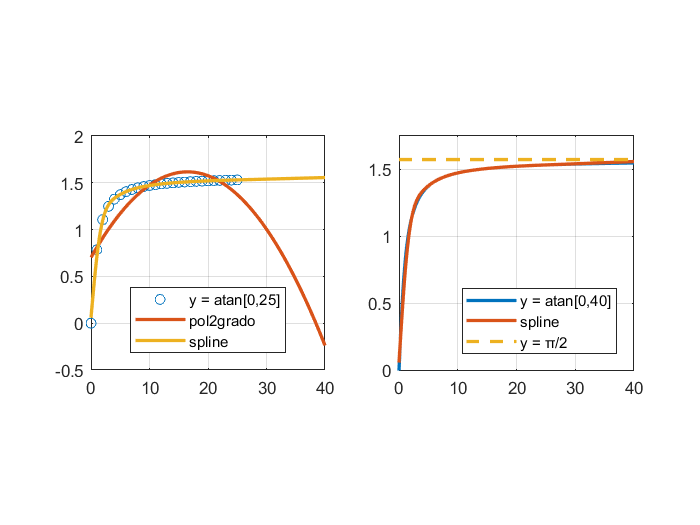

x=0:25;y=atan(x);   % atan in [0,25]
pp = fnxtr(csaps(x,y,.85));
p = polyfit(x,y,2);

x_a=0:0.1:40; 
f = polyval(p,x_a); % polinomio
ys=ppval(pp,x_a);   % spline

y_a=atan(x_a);  % atan in [0,40]
const(1:length(x_a))=pi/2;  % asintoto orizzontale

figure(1)
subplot(1,2,1), p1 = plot(x,y,'o',x_a,f,x_a,ys); grid, legend('y = atan[0,25]','pol2grado','spline','Location','south'),axis square
subplot(1,2,2), p2 = plot(x_a,y_a,x_a,ys,x_a,const,'--'); grid, legend('y = atan[0,40]','spline','y = π/2','Location','southeast'),axis([0 40 0 1.75]),axis square
p1(2).LineWidth = 2; p1(3).LineWidth = 2; p2(1).LineWidth = 2; p2(2).LineWidth = 2; p2(3).LineWidth = 2;

Visivamente, la maggior accuratezza della spline è piuttosto evidente. Ad ogni modo, per darne una prova concreta è stato calcolato il *residuo* come misura dello scostamento della curva interpolante rispetto a quella vera.

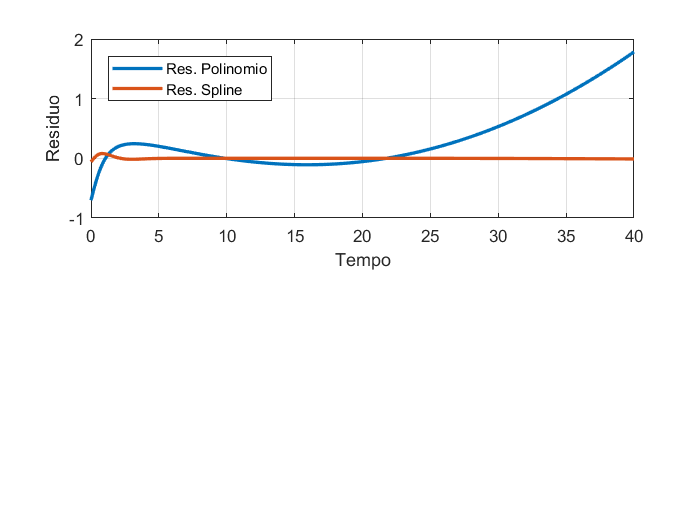

res_pol = y_a - f;
res_spl = y_a - ys;

figure(2)
data = [res_pol' res_spl'];
subplot(2,1,1), p = plot(x_a,data); xlabel('Tempo'), ylabel('Residuo'), legend('Res. Polinomio', 'Res. Spline','Location','northwest'), grid;
p(1).LineWidth = 2;
p(2).LineWidth = 2;

## Interpolazione di curve parametriche bidimensionali

Di seguito si riporta un esempio di interpolazione del *Nastro di Moebius*, una curva parametrica bidimensionale non orientabile (dopo aver percorso idealmente un giro, ci si trova dalla parte opposta della superficie) [2].

Innanzitutto è stato costruita la superficie parametrica come segue:

u = linspace(0,2*pi,7);
v = linspace(-0.5,0.5,7);
[u,v] = meshgrid(u,v);

x = (1+v.*cos(u/2)).*cos(u);
y = (1+v.*cos(u/2)).*sin(u);
z = v.*sin(u/2);

Il numeri di punti analizzati è molto piccolo per cui un plot attuale genera una superficie poco liscia e non regolare:

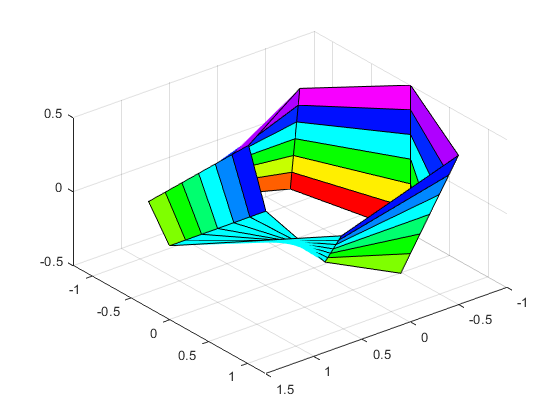

figure(4)
surf(x,y,z), colormap hsv
view([20,25,30])

 Si è quindi proceduto ad eseguire l'interpolazione con la funzione `interp2` utilizzando come `method` la spline:

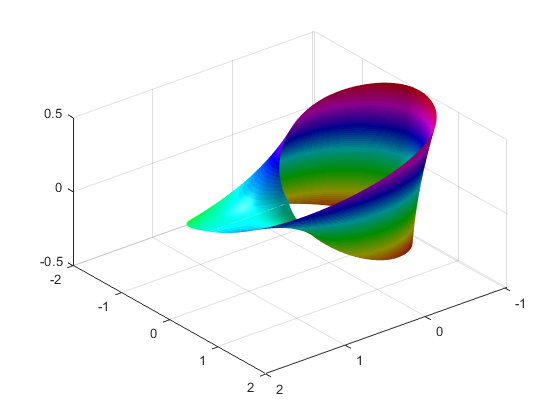

[ui,vi] = meshgrid(0:0.01:2*pi,-0.5:0.01:0.5);

xx = interp2(u,v,x,ui,vi,'spline');
yy = interp2(u,v,y,ui,vi,'spline');
zz = interp2(u,v,z,ui,vi,'spline');
figure(1)
surfl(xx,yy,zz,'light'), colormap hsv, shading interp
view([20,25,30])

## Interpolazione e tracciamento dei contorni di un oggetto

In questo esempio si è sviluppato un tool che permette di tracciare i contorni di uno o più oggetti all'interno di un'immagine a partire dai punti inseriti "a mano" dall'utente: l'obiettivo è quello di realizzare una versione semplificata dello strumento *lazo* che utilizzano tutti i software di photo editing.

Per utilizzare il tool bisogna:

- Lanciare lo script `detect_contour;`

- Disegnare i punti sulla finestra grafica di cui vuole ottenere il contorno;

- Premere `Enter` per terminare l'inserimento ed eseguire il tracciamento.

Il sistema che traccia i contorni è stato realizzato utilizzando la spline interpolante parametrica: è necessario infatti interpolare entrambe le funzioni definite dai `[x,y]` ottenuti con `ginput.` Di seguito si riporta il risultato ottenuto con l'immagine di test:

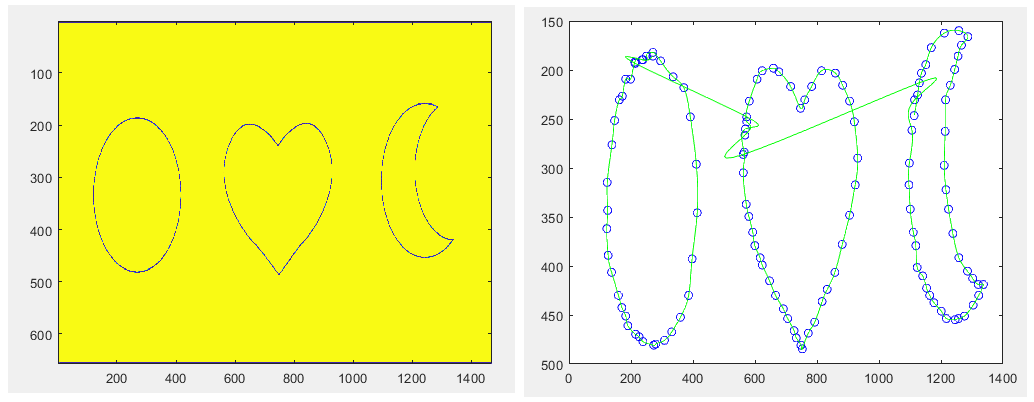

# Smoothing di dati

In questo capitolo saranno presentate le funzionalità del Matalb viste a lezione per quanto riguarda lo smoothing di dati: verrà descritta una serie di esempi applicativi concentrandosi infine sulle applicazioni di tali tecninche alle immagini.

## Temperature medie in Groenlandia

In questo caso i dati sono stati recuperati dalla rete [4] e riguardano le temperature medie annuali misurate in Groenlandia a partire dal 1901 fino al 2012.

In primo luogo è stata utilizzata una tecnica di interpolazione lineare a tratti dalla quale si può osservare che l'escursione termica complessiva si aggira intorno ai 3°.

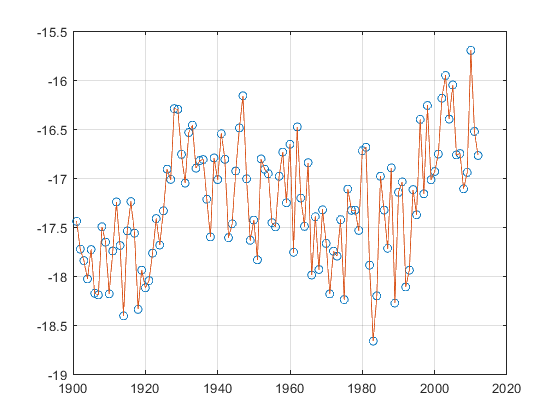

url = 'http://climatedataapi.worldbank.org/climateweb/rest/v1/country/cru/tas/year/grl';
options = weboptions('Timeout',Inf);  % durata connessione
data = webread(url,options);
format_data = table2array(struct2table(data));
year = format_data(:,1);
temperature = format_data(:,2);
t = 1901:0.1:2012;
z = interp1(year,temperature,t); % interpolazione lineare a tratti
plot(year,temperature,'o',t,z), grid

Applicando le tecniche di smoothing viste a lezione invece è possibile scoprire nuove informazioni: 

- La spline definisce un comportamento più regolare della funzione assumendo che i valori discreti siano affetti da un errore di misurazione;

- La retta dei minimi quadrati evidenzia come nel corso del secolo la temperatura sia mediamente aumentata per un'escursione termica complessiva di circa 1°. Questa analisi è utile ai fini di quantificare il problema dello scioglimento dei ghiacciai.

OSS: il poliniomo di secondo grado, pur evidenziando un comportamento crescente, non può essere usato per alcuna analisi in quanto come negli esempi precedenti la presenza di molti punti lo rende mal condizionato.

coeff1 = polyfit(year,temperature,1);
coeff2 = polyfit(year(1:10:112),temperature(1:10:112),2);

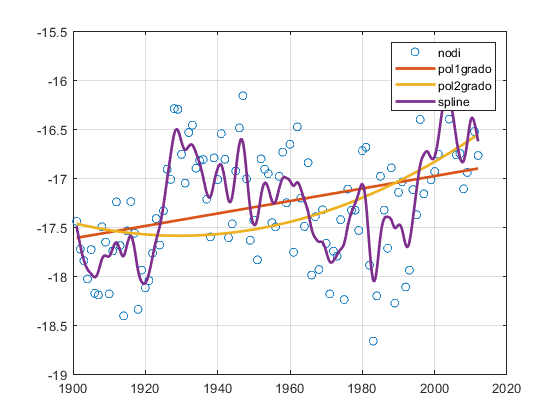

t = 1901:0.1:2012;
f1 = polyval(coeff1,t);
f2 = polyval(coeff2,t);
pp = csaps(year,temperature,0.5);
ys1 = ppval(pp,t);
p = plot(year,temperature,'o',t,f1,t,f2,t,ys1); grid, legend('nodi','pol1grado','pol2grado','spline')
p(4).LineWidth = 2; p(2).LineWidth = 2; p(3).LineWidth = 2;

## Performance di algoritmi

In questa applicazione le tecniche di smooting sono state utilizzate per stimare la complessità computazionale di un algoritmo: l'idea di base è eseguire N esecuzioni con dimensioni crescenti dell'input e misurarne il tempo di esecuzione; si ottengono quindi N misurazioni affette da un errore dovuto alla situazione di carico del calcolatore e alla gestione che il sistema operativo fa del processo che esegue l'algoritmo.

Nel seguente esempio l'algoritmo preso in considerazione è quello del `PageRank `e la tecnica di smoothing utilizzata è il polinomio di secondo grado dei minimi quadrati.

clear

N=1000;
T=zeros(1,N);

for i=1:N
     G = rand(i);
     G(G<0.7) = 0;
     G = sparse(logical(G));
     tic;
     PageRank(G);
     T(i)=toc;
end


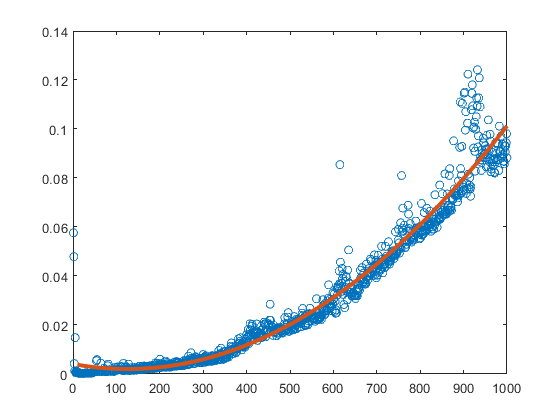

x = linspace(1,N,N);
c=polyfit(x,T,2);
t=10:0.001:N;
v=polyval(c,t);
figure
p = plot(x,T,'o',t,v);
p(2).LineWidth = 3;

Si può osservare che il carico a cui è sottoposto il calcolatore per dimensioni dell'input superiori a 500 è significativo e quindi si ottengono misurazioni molto differenti tra loro; in ogni caso, il polinomio di secondo grado dei minimi quadrati riesce a minimizzare gli errori di misurazione restituendo una curva che si può assumere essere quella che descrive la complessità computazionale dell'algoritmo.

## Interpolazione e qualità delle immagini

Attraverso l'interpolazione è possibile migliorare la qualità di immagini sgranate. Per effettuare un'analisi, carichiamo un'immagine e ridimensioniamola in modo tale da ottenere un'immagine di scarsa qualità (con pochi pixel):

Im = imread('prova.png');
I = imresize(Im, [64 NaN]);

Adesso, preallochiamo le nuove immagini e generiamo una griglia di pixel più fitta. Saranno preallocate 2 immagini perché verrà mostrata sia l'interpolazione lineare che con spline.

[r,c,v] = size(I);
x = 1:c; y = 1:r;
NEW_I = zeros(5*r,5*c,v,'uint8');
NEW_I_L = zeros(5*r,5*c,v,'uint8');
new_x = linspace(1,c,5*c)';
new_y = linspace(1,r,5*r);

A questo punto, possiamo effettuare l'interpolazione sulla griglia originale, valutando l'interpolante nei nuovi punti (si veda la documentazione di `interp2`):

for i=1:3
    NEW_I(:,:,i)=uint8(interp2(x,y,double(I(:,:,i)),new_x,new_y,'spline'));
    NEW_I_L(:,:,i)=uint8(interp2(x,y,double(I(:,:,i)),new_x,new_y,'linear'));
end

Stampiamo i risultati:

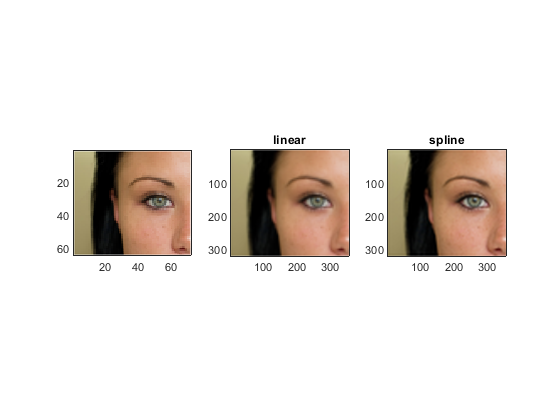

subplot(1,3,1), subimage(I)
subplot(1,3,2), subimage(NEW_I_L),title('linear')
subplot(1,3,3), subimage(NEW_I),title('spline')

Effettuiamo uno zoom per mettere in evidenza il miglioramento della qualità dell'immagine: in particolare, sono migliorati sia il contrasto che la nitidezza.

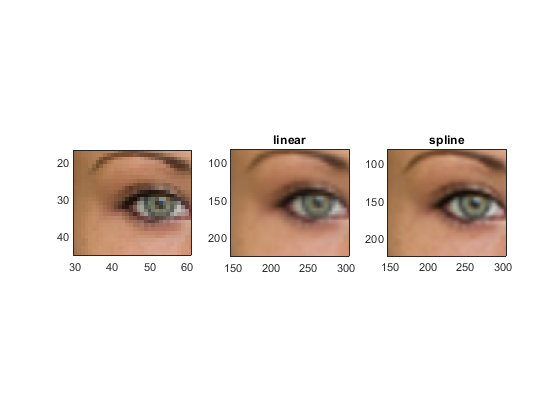

subplot(1,3,1), subimage(I)
subplot(1,3,2), subimage(NEW_I_L),title('linear')
subplot(1,3,3),subimage(NEW_I),title('spline')

subplot(1,3,1)
xlim([29.4 61.4])
ylim([16.8 45.2])
subplot(1,3,2)
xlim([146 306])
ylim([83 226])
subplot(1,3,3)
xlim([146 306])
ylim([82 224])

# Approfondimento: Superfici e oggetti 3D

Per quanto riguarda l'esempio di *surface plot* descritto a lezione si è deciso di approfondire l'argomento analizzando come si potesse modificare la superficie di un oggetto tridimensionale. In particolare, sono stati utilizzate le funzioni messe a disposizione nella community di Mathworks [1] e degli esempi disponibili in rete.

Le istruzioni chiave che permettono l'elaborazione sono le seguenti:

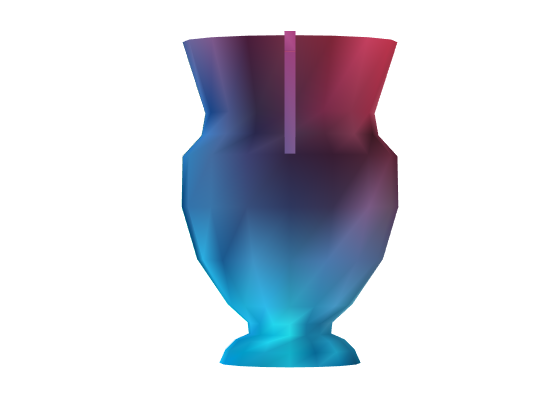

my_obj=readObj('vaso.obj');
display_obj(my_obj,'vaso1.jpg');

N.B. La funzione `display_obj` plotta solo la sezione frontale dell'oggetto; per verificare l'applicazione completa della texture all'oggetto 3D eseguire lo script `object3d` messo a disposizione, sono mostrati due screen a titolo esemplificativo:

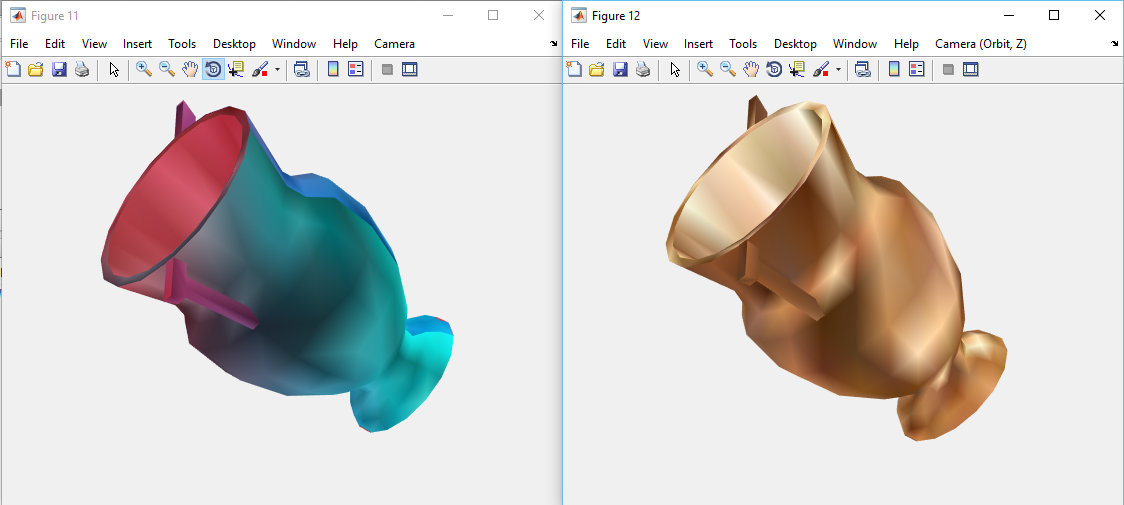

## Riferimenti

[1] Mathworks Community, [https://it.mathworks.com/matlabcentral/profile/authors/84765-bernard-abayowa](https://it.mathworks.com/matlabcentral/profile/authors/84765-bernard-abayowa)

[2] Wikipedia, [https://it.wikipedia.org/wiki/Nastro_di_M%C3%B6bius](https://it.wikipedia.org/wiki/Nastro_di_M%C3%B6bius)

[3] Econometrics Toolbox, [https://it.mathworks.com/help/econ/data-sets-and-examples.html](https://it.mathworks.com/help/econ/data-sets-and-examples.html)

[4] The world bank, [https://datahelpdesk.worldbank.org/knowledgebase/articles/902061-climate-data-api](https://datahelpdesk.worldbank.org/knowledgebase/articles/902061-climate-data-api)

## Autori

Valerio La Gatta, Marco Postiglione